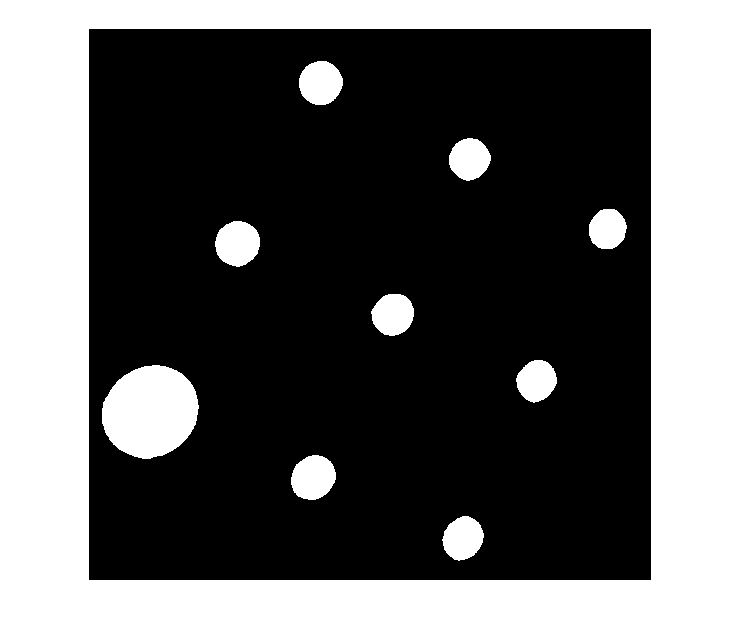

clear All; close all; 

img = imread("cameraview01.png");
[bw, centroids] = segment_blue3(img);

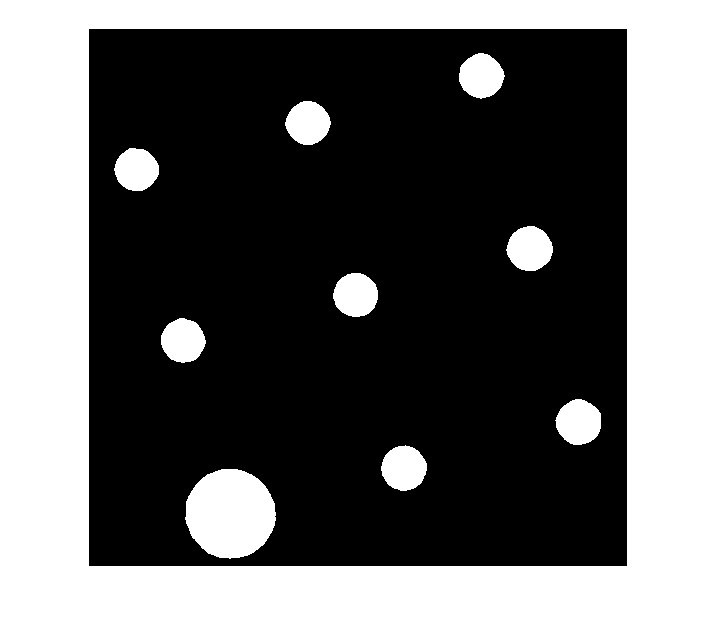


img = imread("cameraview02.png");
[bw, centroids] = segment_blue3(img);


% function
[H,S,V] = rgb2hsv(img);
% Examine the image and binarize blue area
blue = H>0.65 & H<0.68;

% Clean noise
blueClean = medfilt2(blue, [8,8]);

% Get props' centroids
stats = regionprops("table",blueClean,"Centroid","Area","Circularity");
% Store data
centroids = cat(1,stats.Centroid);
areas = cat(1,stats.Area);
circularity = cat(1,stats.Circularity);

binary_img = imbinarize(double(blueClean));
figure();
imshow(binary_img);

% Largest circle
largestArea = max(areas)

largestArea = 6343

locationLargest = find(areas == largestArea)

locationLargest = 3

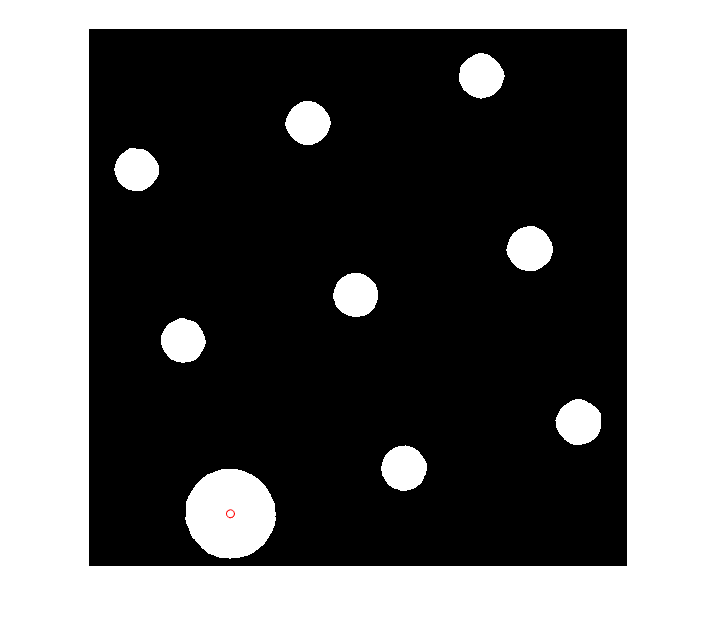


hold on;
plot(centroids(locationLargest,1), centroids(locationLargest,2), 'ro');